# Intro

% This main script will outline the story for our animation. It will
% implement various transformation functions in loops to animate a character.

% Each of us will be responsible for one of these scenes. Once we figure out a 
% story, we should include the expected inputs and outputs.

## Animation

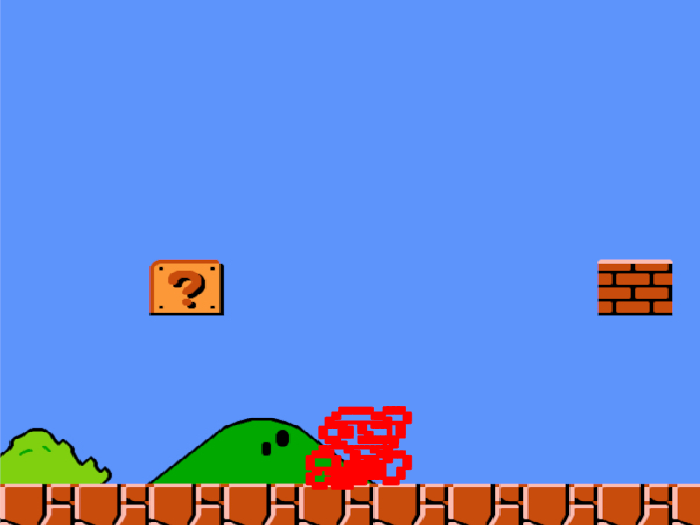

% SCENE 1 
% (Panning Camera) Large background, smaller view follows mario
% Background:SunnyMarioLevel.jpg
% est Duation:28 seconds 

clf
% images to 3x3 matrices
Jmario = imread('jumpingmario.jpg');
mushroom = imread('mushroom.jpg');
goomba = imread('goomba.jpg');
Jmario = Jpeg2pointsConverter(Jmario, 150);
mushroom = Jpeg2pointsConverter(mushroom, 200);
goomba = Jpeg2pointsConverter(goomba, 150);
Jmario(3,:) = ones(1, length(Jmario));
mushroom(3,:) = ones(1, length(mushroom));
goomba(3,:) = ones(1, length(goomba));

clf
% establishing background
ha = axes('units','normalized', 'position',[0 0 1 1]); 
uistack(ha,'bottom');
bg = imread('SunnyMarioLevelV2.jpg');
hi = imagesc(bg(400:1000,1:600, 1:3));
hb = axes('position',[0 0 1 1]);
set(ha,'handlevisibility','on', 'visible','off')
hold on; 
% scaling

mushroom = scale(mushroom, 1/8, 1/8);
Jmario = scale(Jmario, .3, .3);
goomba = scale(goomba, .2, .2);
axis([0 800 0 800]); axis manual
mushroom = translate(mushroom, 600, 50);
Jmario = translate(Jmario, 0, 60);
h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
h_mushroom = scatter(hb, mushroom(1, :), mushroom(2, :), 'k.');

set(gca,'color','none','handlevisibility','off','visible','off');
% Mario standing still and further away mushroom. (2 Seconds)
% No transformations, Stand still frame  
% Standing Mario, Mushroom
pause(.2)

% Mario does a flip in and air and lands back down (3 seconds)
% Mario shifts and rotates
% Asset(s): Standing Mario, Jumping Mario, Mushroom
% R = [cos(pi/18) -sin(pi/18) 0; sin(pi/18) cos(pi/18) 0; 0 0 1];
for i = 1:12
     Jmario = translate(Jmario, 0, 30);
     Jmario = Rotate2(Jmario, pi/12);
     delete(h_Jmario);
     h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
     pause(.05)
end

for i = 1:12
     Jmario = translate(Jmario, 0, -30);
     Jmario = Rotate2(Jmario, pi/12);
     delete(h_Jmario);
     h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
     pause(.05)
end


pause(.2);

% Mario stands in place and Mushroom shimmies offscreen (3 seconds)      
% Mushroom shifts offscreen (shifts)
% Asset(s): Standing Mario, Mushroom
% pause(1.5)
for i = 1:12
    mushroom = translate(mushroom, 50, 0);
    delete(h_mushroom);
    h_mushroom = scatter(hb, mushroom(1, :), mushroom(2, :), 'k.');
    pause(.1);
end


% Mario runs after mushroom and camera follows (3 seconds)
% Mario shifts right, and rotates clockwise and counterclockwise looks like a wobble
% Asset(s): Standing Mario, Jumping Mario, 
for i = 1:10
    Jmario = translate(Jmario, 35, 0);
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
    pause(.1);
end

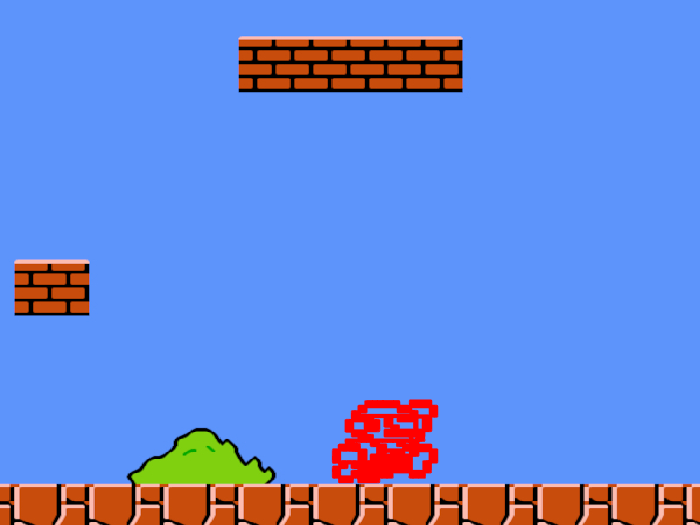


bgxstart = 1;
bgxend = 600;
for i = 1:10
    if i == 8 
        goomba = translate(goomba, 800, 60);
        h_goomba = scatter(hb, goomba(1, :), goomba(2, :), 'k.');
    end 
    if i >8 && i <= 10
        goomba = translate(goomba, -50, 0);
        goomba = reflectV2(goomba, 'y');
        delete(h_goomba)
        h_goomba = scatter(hb, goomba(1, :), goomba(2, :), 'k.');
    end
    clf
    bgxstart = bgxstart +50; 
    bgxend = bgxend +50;
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
    set(ha,'handlevisibility','on', 'visible','off')
    pause(.2);
end


% Brown Goomba walks toward Mario, Mario stops goes backward, and jumps on it(5 seconds) 
% Goomba reflections and shifts, Mario shifts 
% Asset(s): Standing Mario, jumping Mario, Big footed Goomba
for i = 1:14
%   Mario backs up
    if i >=2 && i<=4
        Jmario = translate(Jmario, -40, 0);
        delete(h_Jmario);
        h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');   
    end
%   Mario jumps up and moves right
    if i >=5 && i <=9
        Jmario = translate(Jmario, 15, 40);
        delete(h_Jmario);
         h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    end
%   Mario's descents and moves right after arch of jumping  
    if i >= 9 && i <= 13
        Jmario = translate(Jmario, 15, -30);
        delete(h_Jmario);
        h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    end
    if i == 13
        goomba = scale(goomba, .5, 1);
        goomba = translate(goomba, 0, 40);
        delete(h_goomba)
        h_goomba = scatter(hb, goomba(1, :), goomba(2, :), 'k.'); 
    end 
%   Mario positions himself correctly on ground
%   goomba becomes pancake
    if i == 14
        Jmario = translate(Jmario, 0, -40);
        goomba = rescale(goomba, .001, 1);
        goomba = translate(goomba, 0, 40);
        delete(h_goomba);
        delete(h_Jmario);
        h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
        h_goomba = scatter(hb, goomba(1, :), goomba(2, :), 'k.');   
    end
%   Goomba moves towards mario, 
    if i >= 1 && i<= 12
        goomba = translate(goomba, -25, 0);
        goomba = reflectV2(goomba, 'y');
        delete(h_goomba);
        h_goomba = scatter(hb, goomba(1, :), goomba(2, :), 'k.');   
    end 
    pause(.1);
end

% deletes pancake goomba
delete(h_goomba);

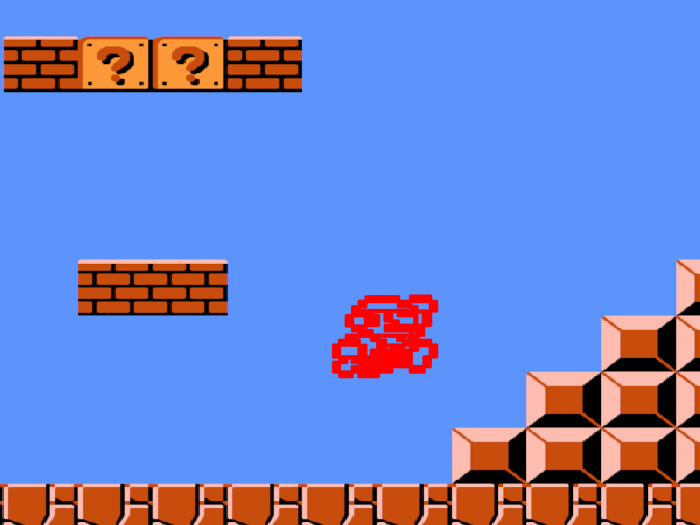



% mario moves forward until he reaches the bottom of the stairs 
for i = 1:13
    clf
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    bgxstart = bgxstart + 50;
    bgxend = bgxend + 50;
    hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
    set(ha,'handlevisibility','on', 'visible','off')
    pause(.2);
end


% Mario jumps up stairs
for i = 1:4
    Jmario = translate(Jmario, 0, 40);
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end

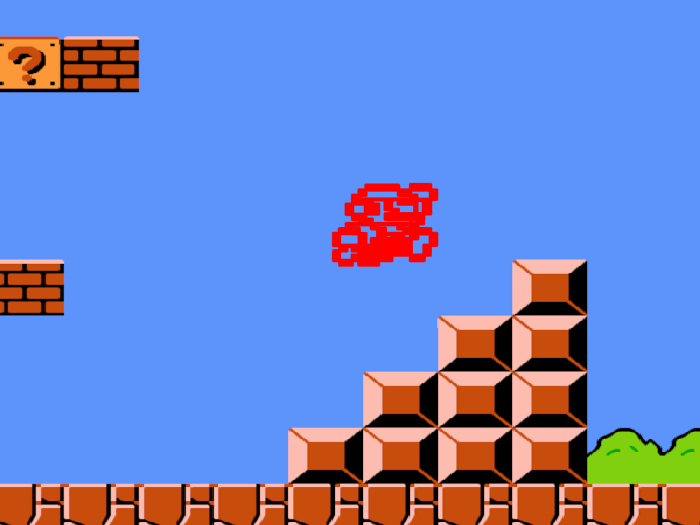

for i = 1:4
    clf
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    if i <= 2
        bgxstart = bgxstart + 40;
        bgxend = bgxend + 40;
        hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
        Jmario = translate(Jmario, 0, 30);
    end
    if i >= 3&& i<=4
        bgxstart = bgxstart + 30;
        bgxend = bgxend + 30;
        hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
        Jmario = translate(Jmario, 0, -25);
    end
    set(ha,'handlevisibility','on', 'visible','off')
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end
for i = 1:4
    Jmario = translate(Jmario, 0, 40);
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end

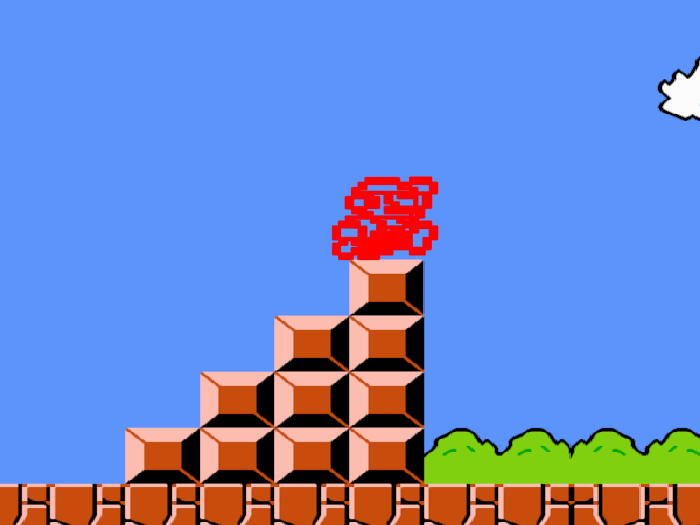

% repeats the same jump up the stairs. 
for i = 1:4
    clf
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    if i <= 2
        bgxstart = bgxstart + 40;
        bgxend = bgxend + 40;
        hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
        Jmario = translate(Jmario, 0, 30);
    end
    if i >= 3&& i<=4
        bgxstart = bgxstart + 30;
        bgxend = bgxend + 30;
        hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
        Jmario = translate(Jmario, 0, -25);
    end
    set(ha,'handlevisibility','on', 'visible','off')
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end

% Mario reaches big gap, stops in place, jumps up and down, then jumps over gap (5 seconds)
% Mario shifts
% Asset(s): Standing Mario, Jumping Mario
pause(.2);
for i = 1:8
    Jmario = translate(Jmario, 0, 30);
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end
for i = 1:8
    Jmario = translate(Jmario, 0, -30);
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end

for i = 1:2
    Jmario = reflectV2(Jmario, 'y');
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.4);
end

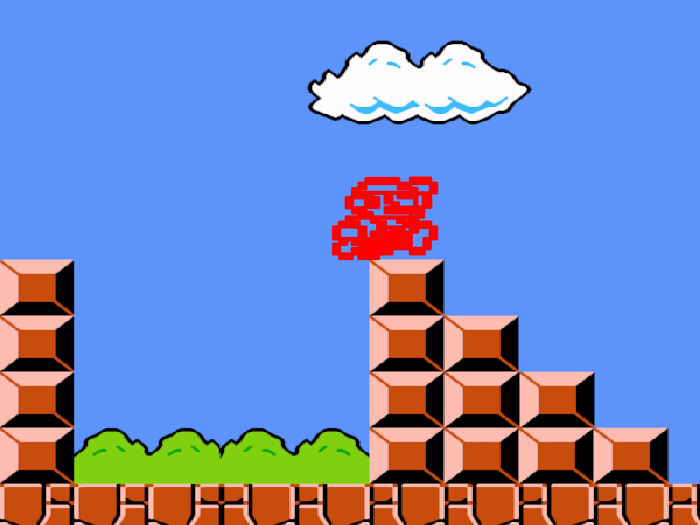


% mario jumps over the gap
for i = 1:12
    if i <= 6 
        Jmario = translate(Jmario, 0, 20); 
    else
        Jmario = translate(Jmario, 0, -20); 
    end
    clf
    Jmario = Rotate2(Jmario, pi/6);
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    bgxstart = bgxstart + 25;
    bgxend = bgxend + 25;
    hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
    set(ha,'handlevisibility','on', 'visible','off')
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end


% flips down the stairs
for i = 1:16
    if i <= 6 
        Jmario = translate(Jmario, 0, 20); 
    elseif i >=7 && i<= 14
        Jmario = translate(Jmario, 0, -50); 
    else
        Jmario = translate(Jmario, 0, -30); 
    end
    clf
    Jmario = Rotate2(Jmario, pi/8);
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    bgxstart = bgxstart + 25;
    bgxend = bgxend + 25;
    hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
    set(ha,'handlevisibility','on', 'visible','off')
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.1)
end

for i = 1:8
    clf
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    bgxstart = bgxstart + 50;
    bgxend = bgxend + 50;
    hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
    set(ha,'handlevisibility','on', 'visible','off')
    pause(.2);
end

% mario sees the mushroom 
pause(1)


for i = 1:10
    Jmario = translate(Jmario, -10, 0);
    if i== 5
        mushroom = translate(mushroom, -400, 0);
    end
    mushroom = translate(mushroom, -20, 0);
    delete(h_Jmario);
    delete(h_mushroom);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    h_mushroom = scatter(hb, mushroom(1, :), mushroom(2, :), 'k.');    
    clf
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    bgxstart = bgxstart + 20;
    bgxend = bgxend + 20;
    hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
    set(ha,'handlevisibility','on', 'visible','off')
    pause(.1);
end

pause(2);

% Mario reaches the not moving mushroom, Mario transforms into a red goomba (3 seconds)
% Mario shifts and morphs(standing Mario-> Big footed Goomba)
% Asset(s): Standing Mario, Mushroom, Big footed Goomba
for i = 1:4
    Jmario = translate(Jmario, 20, 0);
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');  
    pause(.2);
end
 
for i = 1:3
    clf
    ha = axes('units','normalized', 'position',[0 0 1 1]); 
    uistack(ha,'bottom');
    bgxstart = bgxstart + 50;
    bgxend = bgxend + 50;
    hi = imagesc(bg(400:1000,bgxstart:bgxend, 1:3));
    set(ha,'handlevisibility','on', 'visible','off')
    mushroom = translate(mushroom, -50, 0);
    delete(h_mushroom);
    h_mushroom = scatter(hb, mushroom(1, :), mushroom(2, :), 'k.');  
    pause(.1);
end

delete(h_mushroom);
% mario morphs
% vv = [250;250;1];
% Extrapts = vv*ones(1,54999);
% % (NOTE TO SELF) added pts has to be smaller than n of (2xn) pic
% Marioextra = [Jmario(:,1:54999), Extrapts, Jmario(:,55000:end)];
% delete(h_Jmario);
% for k=0:1/6:1
% 
%     redgoomba = (1-k)*Marioextra + k*goomba;
%     redgoombad= [redgoomba; ones(1,length(redgoomba(2,:)))];
%     if i>= 2
%         delete(h_redgoombad);
%     end
%     h_redgoombad = scatter(hb,redgoombad(1,:),redgoombad(2,:), 'r.');
%     pause(0.2);
% end
% Note to self, Depending on whichever one has the larger pixel size, Add
% columns to n so that they equal out. 
% adding points to top of head

% Goomba Mario stops and wobbles in place, and proceeds toward the end of level (4 seconds)
% Goomba Mario Shears left and right (wobble), Reflections and shifts after
% Asset(s): Big footed Goomba

% Goomba Mario goes down pipe (2 seconds)
% Shears downward like a pankcake.
% Asset(s): Red Goomba
% end


% SCENE 2

% SCENE 3

% SCENE 4